clear all;
clc;

## Reading File:

[file,path] = uigetfile({'*.wav';'*.m4p';'*.mp4';'*.mp3'},...
                          'File Selector');
[x,Fs] = audioread(file);
x(:,2)=x(:,1);

## Sample rate:

fprintf("sample rate =   %d  " , Fs);

sample rate =   48000  

## drawing graph:

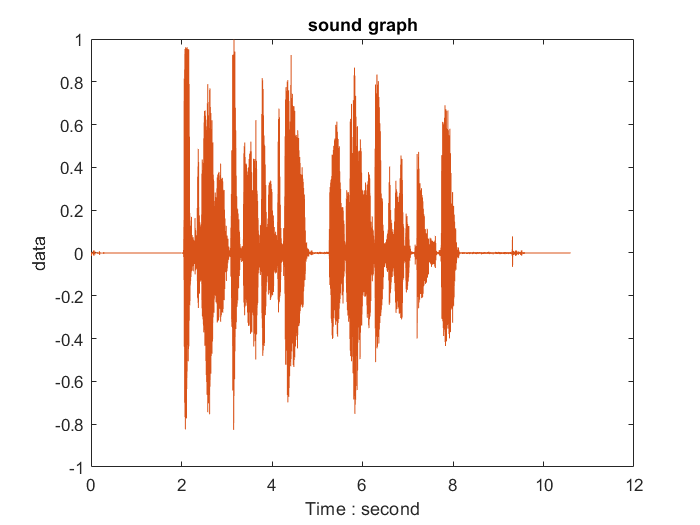

xlen=length(x);
T = xlen/Fs;
time_axis_input = ([1:xlen]-1)/Fs;
plot(time_axis_input, x);
title('sound graph')
xlabel('Time : second')
ylabel('data')

## listening :

sound(x,Fs);

## writing sound(saving):

audiowrite('x.wav',x,Fs);

## Adding echo:

a=0.9%echo strength

a = 0.9000

delay=1 % 1s dalay

delay = 1

N0=delay *Fs;
power = (sum(x.^2))/length(x);
xe = 0.9 .* x;
power2 = (sum(xe.^2))/length(xe);
disp(power2/power);

    0.8100




% calculate the time value of samples
h = zeros(size(x,1),1);%Impulse

% Generate impulse train
h(1)=1;
h(delay*Fs) =a;
y=[conv(x(:,1),h(:,1)),conv(x(:,1),h(:,1))]

y =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


audiowrite('y.wav',y,Fs);

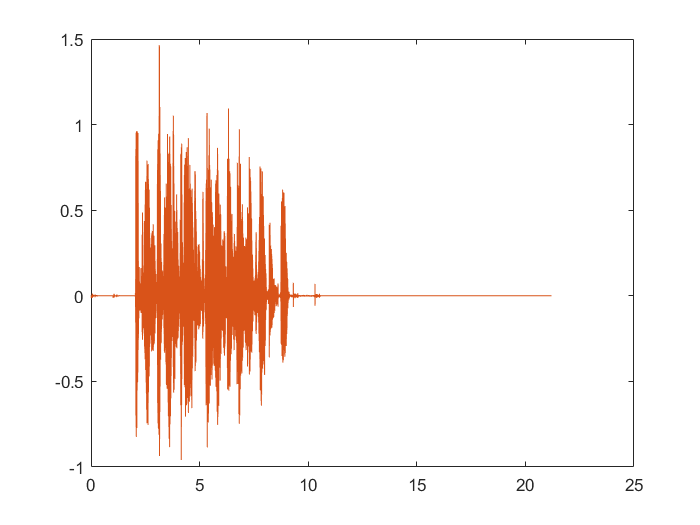

s = ([1:length(y)]-1)/Fs;
plot(s,y)

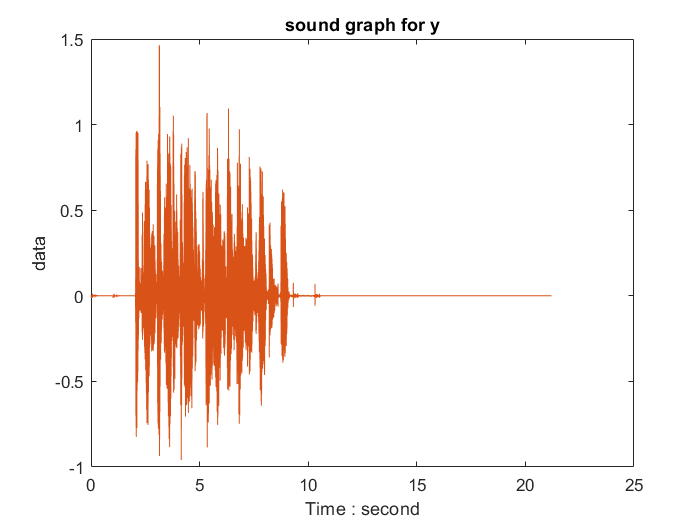

plot(s, y);
title('sound graph for y')
xlabel('Time : second')
ylabel('data')

sound(y,Fs)



## adding noise:

noise = randn(size(y))

noise =     0.5377   -0.4825
    1.8339   -1.0821
   -2.2588    1.4085
    0.8622    0.6846
    0.3188    0.1493
   -1.3077   -0.2251
   -0.4336    0.4515
    0.3426    0.1511
    3.5784    0.4298
    2.7694    0.2428


maxy=max(y)

maxy =     1.4644    1.4644


y_noise = y + 0.1 * noise * maxy(1,1) ;



audiowrite('noise_y.wav',y_noise,Fs);

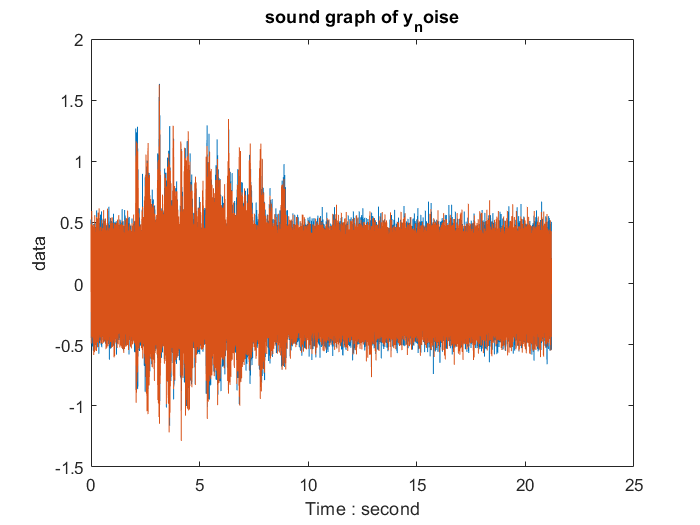

sound(y_noise,Fs);
plot(s, y_noise);
title('sound graph of y_noise')
xlabel('Time : second')
ylabel('data')

## finding n0 & a from y and x:


mono_x=x(:,1)

mono_x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


mono_x_C= mono_x'

mono_x_C =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


[rx,cx] = size(x)

rx = 508799

cx = 2

lenx=length(x)

lenx = 508799

leny=length(y)

leny = 1017597

[ry,cy] = size(y)

ry = 1017597

cy = 2

x_extend=[mono_x_C zeros(1,leny-lenx)]

x_extend =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y_C=y(:,1)'

y_C =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



yecho=y_C-x_extend

yecho =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0





[xc,lags] =xcorr(mono_x_C,yecho);
[~,I] = max(abs(xc));
[a,~] = size(y)

a = 1017597

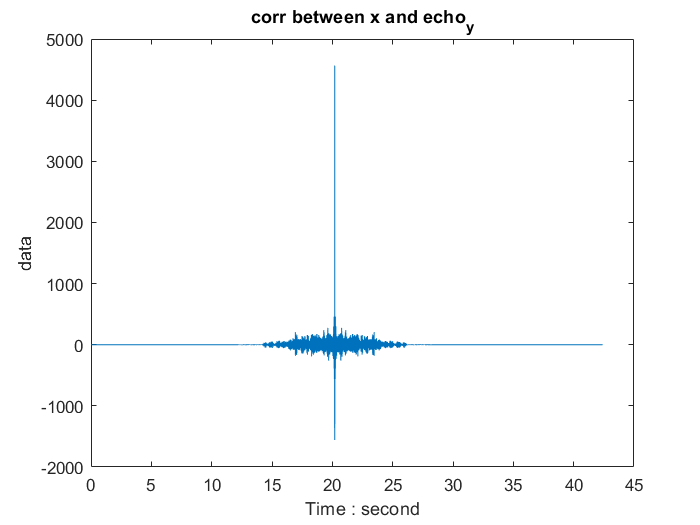


corrlen=length(xc);
time_axis_input = ([1:corrlen]-1)/Fs;
plot(time_axis_input, xc);
title('corr between x and echo_y')
xlabel('Time : second')
ylabel('data')




data_shifted=a-I

data_shifted = 47999

n0_yx=data_shifted/Fs

n0_yx = 1.0000


a_yx=max(yecho)/max(x_extend)

a_yx = 0.9000

## finding n0 & a from y_noise and x:

mono_y_noise=y_noise(:,1)'

mono_y_noise =     0.0787    0.2686   -0.3308    0.1263    0.0467   -0.1915   -0.0635    0.0502    0.5240    0.4056   -0.1977    0.4444    0.1062   -0.0092    0.1047   -0.0300   -0.0182    0.2182    0.2063    0.2075    0.0983   -0.1768    0.1050    0.2387    0.0716    0.1515    0.1064   -0.0444    0.0430   -0.1153    0.1301   -0.1680   -0.1565   -0.1185   -0.4312    0.2106    0.0476   -0.1106    0.2007   -0.2506   -0.0150   -0.0354    0.0467    0.0458   -0.1267   -0.0044   -0.0241    0.0919    0.1601    0.1624



yecho_with_noise=mono_y_noise-x_extend

yecho_with_noise =     0.0787    0.2686   -0.3308    0.1263    0.0467   -0.1915   -0.0635    0.0502    0.5240    0.4056   -0.1977    0.4444    0.1062   -0.0092    0.1047   -0.0300   -0.0182    0.2182    0.2063    0.2075    0.0983   -0.1768    0.1050    0.2387    0.0716    0.1515    0.1064   -0.0444    0.0430   -0.1153    0.1301   -0.1680   -0.1565   -0.1185   -0.4312    0.2106    0.0476   -0.1106    0.2007   -0.2506   -0.0150   -0.0354    0.0467    0.0458   -0.1267   -0.0044   -0.0241    0.0919    0.1601    0.1624




[xc,lags] =xcorr(mono_x_C,yecho_with_noise);
[~,I] = max(abs(xc));
[a,~] = size(y)

a = 1017597

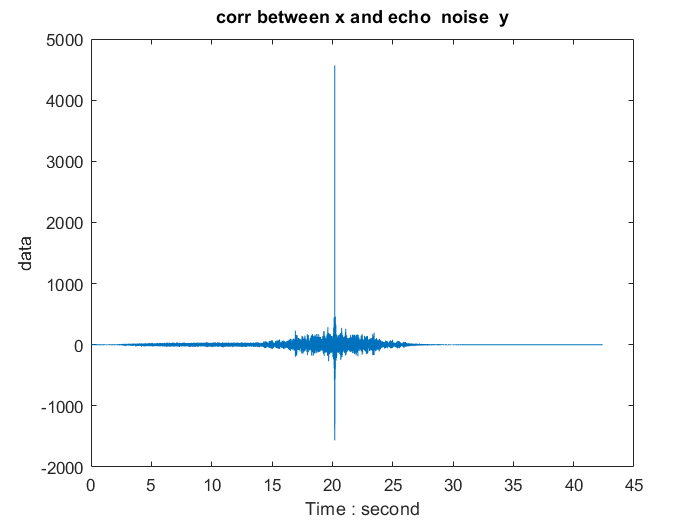


corrlen=length(xc);
time_axis_input = ([1:corrlen]-1)/Fs;
plot(time_axis_input, xc);
title('corr between x and echo _ noise _ y')
xlabel('Time : second')
ylabel('data')





data_shifted=a-I

data_shifted = 47999

n0_ynoise_x=data_shifted/Fs

n0_ynoise_x = 1.0000


a_ynoise_x=max(yecho_with_noise)/max(x_extend)

a_ynoise_x = 1.1618